
D = 'Alfabet/';
p = "*.jpg";       %*
S = dir(fullfile(D,p));

for k = 1:numel(S)
    F = fullfile(D,S(k).name);
    I = imread(F);
    
    imgray = rgb2gray(I);
    I = imbinarize(imgray);
    
    abc{k} = I;
    
    figure;
end

abecedari = {'0','1','2','3','4','5','6','7','8','9','A','B','C','D','E','F','G','H','I','J','K','L','M','N','O','P','Q','R','S','T','U','V','W','X','Y','Z'}

abecedari = 1×36 cell array
    {'0'}    {'1'}    {'2'}    {'3'}    {'4'}    {'5'}    {'6'}    {'7'}    {'8'}    {'9'}    {'A'}    {'B'}    {'C'}    {'D'}    {'E'}    {'F'}    {'G'}    {'H'}    {'I'}    {'J'}    {'K'}    {'L'}    {'M'}    {'N'}    {'O'}    {'P'}    {'Q'}    {'R'}    {'S'}    {'T'}    {'U'}    {'V'}    {'W'}    {'X'}    {'Y'}    {'Z'}


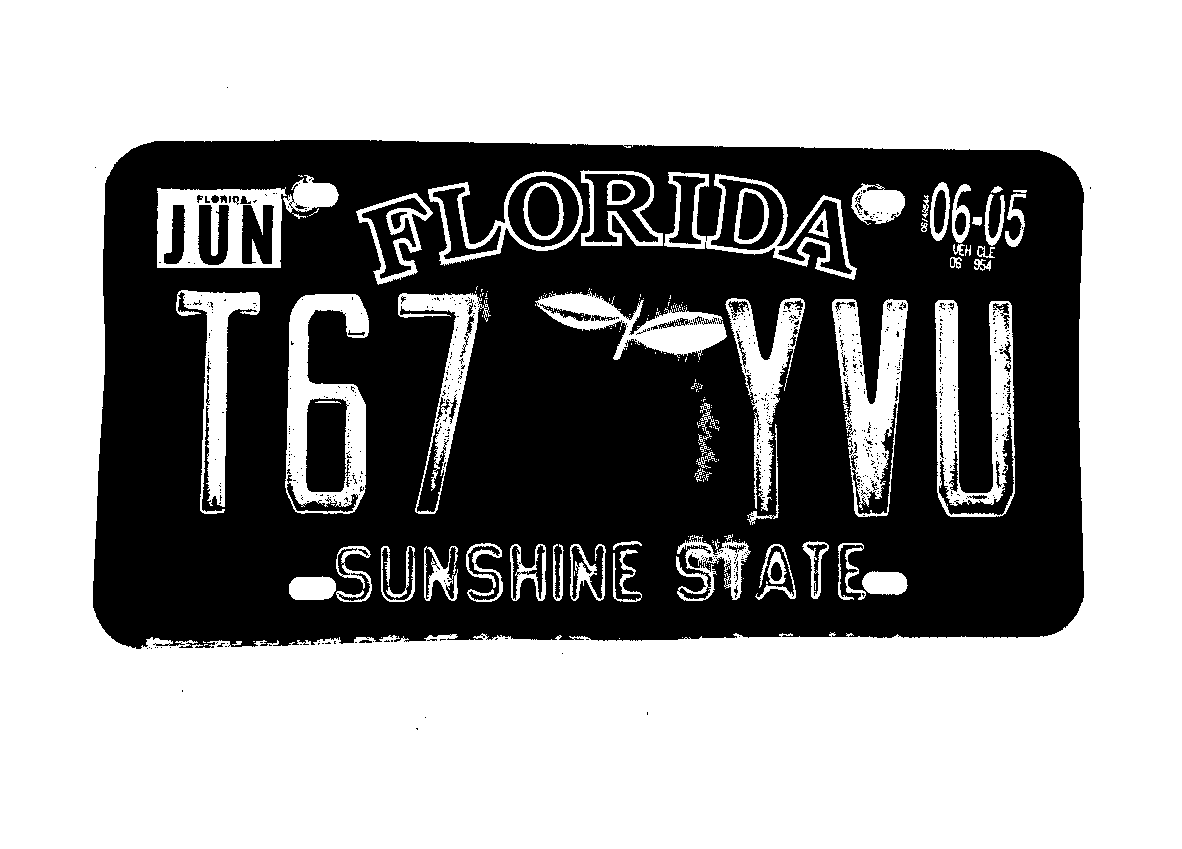

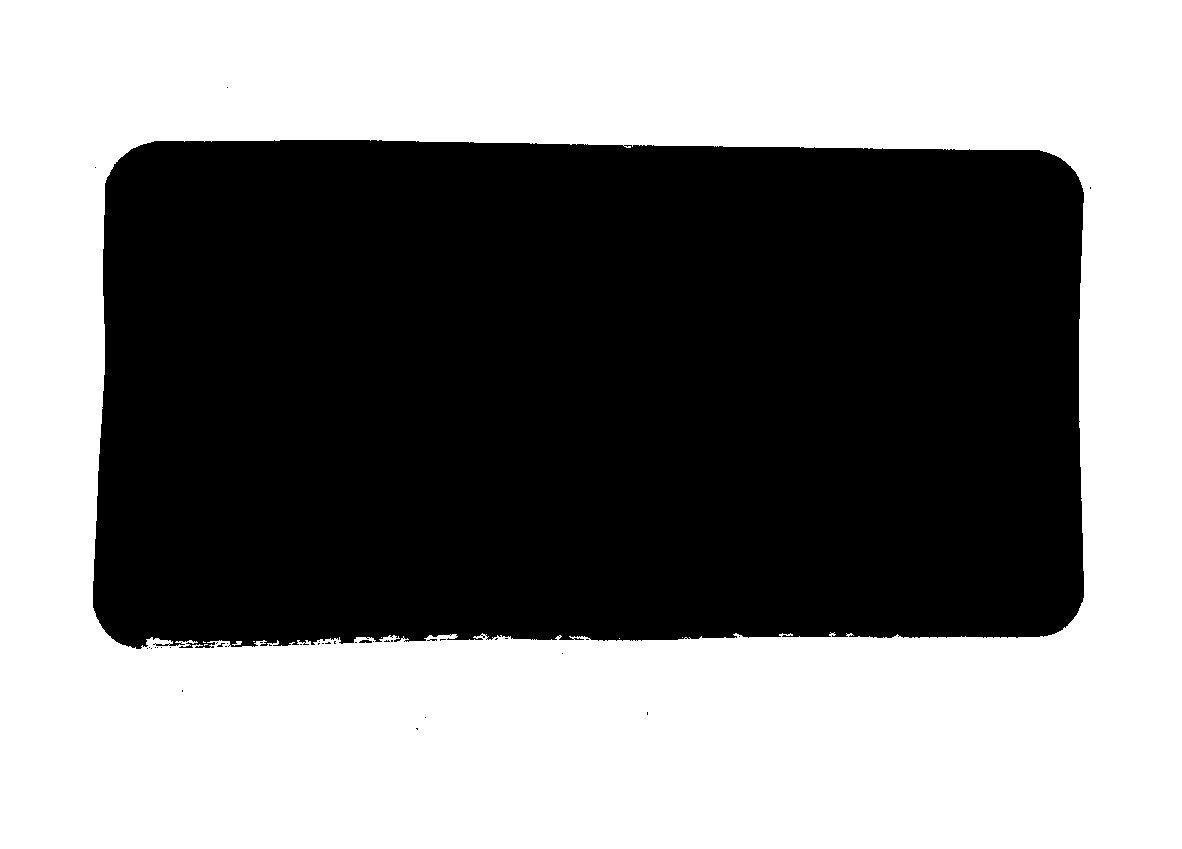

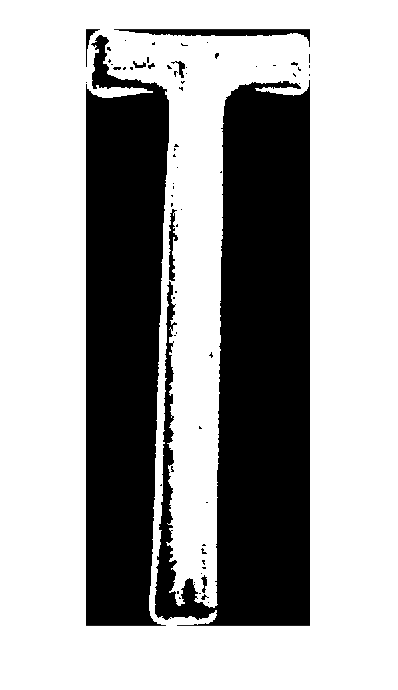

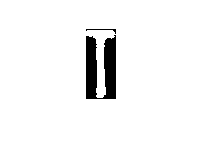

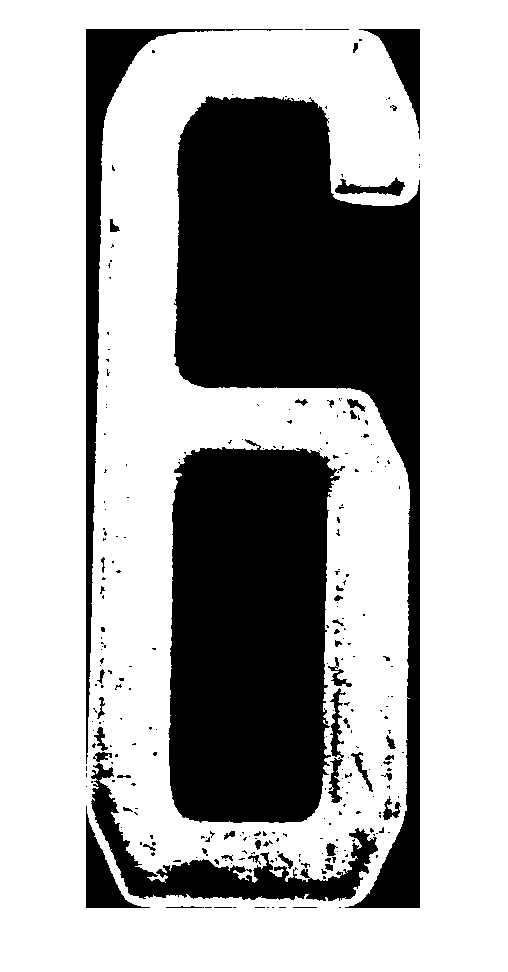

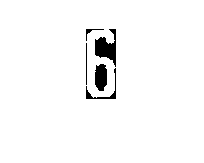

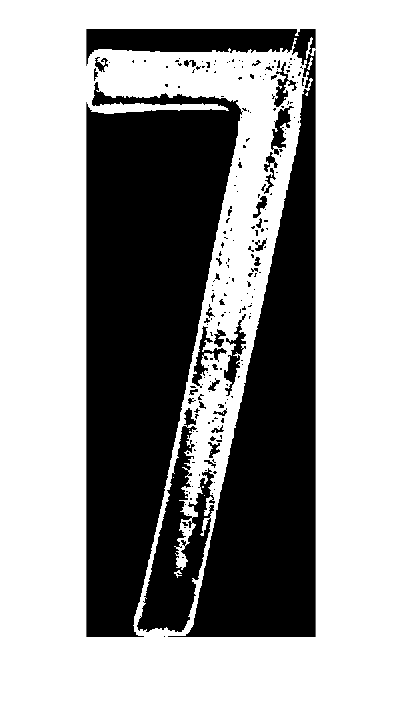

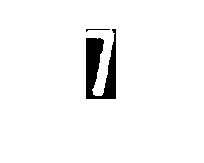

D = 'MLab/';
p = "*.jpg";       %*
S = dir(fullfile(D,p));

totalPlates = numel(S);
counterFoundCorrectly = 0;
counterListByElements = [0,0,0,0,0,0];
platesRealName = {};
platesReadedName ={};

for k = 1:totalPlates
    F = fullfile(D,S(k).name);
    I = imread(F);
    
    imgray = rgb2gray(I);
    I = imbinarize(imgray);
    
    I = bwareaopen(~I, 500);
    
    [h, w] = size(I);
    
    %read letter
    regions_matricula=regionprops(I,'BoundingBox','Area', 'Image');
    count_regions = numel(regions_matricula);
    
    imshow(I);
    figure;
    elementsLlegits = {'','','','','',''};
    contador=1;
    for i=1:count_regions
        
        propWidth = length(regions_matricula(i).Image(1,:));
        propHeight = length(regions_matricula(i).Image(:,1));
        
        if propWidth > 200 && propHeight > 750
            imshow(regions_matricula(i).Image);
            figure;
            regio_processar = imresize(regions_matricula(i).Image,[70 30]);
            maxim = 0.5;
            trobat = 0;
            
            for l=1 : numel(abc)
                lletra_comprovar = imresize(abc{l},[70 30]);
                comparacio = corr2(regio_processar, lletra_comprovar);
                c = comparacio;
                
                if (c > maxim)
                    maxim = c;
                    imshow(abc{l});
                    figure;
                    letter = abecedari{l};
                    %elementsLlegits{contador} = letter;
                    %contador = contador + 1;
                    trobat = 1;
                end
            end
            if trobat == 1
                
                %imshow(letter);
                %figure;
                %letter = abecedari{l};
                elementsLlegits{contador} = letter;
                contador = contador + 1;
                trobat = 0;
            end
        end
    end
    
    readedPlate = strcat(elementsLlegits{:});
    realPlate = split(F,'\');
    realPlate = split(realPlate{2},'.');
    realPlate = realPlate{1};
    
    if strcmp(realPlate, readedPlate)
        counterFoundCorrectly = counterFoundCorrectly + 1;
    end
    
    platesRealName{k} = realPlate;
    platesReadedName{k} = readedPlate;
    
end




disp('The result is:');

The result is:


disp([' - Number of plates: ', num2str(totalPlates)]);

 - Number of plates: 3


disp([' - Number of plates recognized correctly: ', num2str(counterFoundCorrectly)]);

 - Number of plates recognized correctly: 2



disp(' ');


disp('Plates by num of letters recognized:');

Plates by num of letters recognized:


for i=1:totalPlates
    disp(['Letters real: ', platesRealName{i}, ', Plate readed: ', platesReadedName{i}])
    
end

Letters real: T67YVU, Plate readed: T67YVU
Letters real: V01KHQ, Plate readed: VG1NQ
Letters real: WTG38N, Plate readed: WTG38N
